## **Tarea Nº1: **

# **Procesamiento y Reconstrucción de Imágenes Médicas**

#### Universidad Técnica Federico Santa Maria

#### Departamento de Informatica - CSSJ - CC

#### ENUNCIADO

**a) Interpolación Trilineal (20 pts): **La siguiente página de Wikipedia ([https://acortar.link/q9pEiw](https://acortar.link/q9pEiw)), muestra matemáticamente como se puede realizar la Interpolación Trilineal. Desarrolle su propio código en forma de función de MATLAB, que reciba como entrada una imagen 3D, y un factor de escalamiento. Por ejemplo ***“im_out = trilineal_XX_YY(im_in, factor)”***, donde: 

- **XX_YY** = iniciales del nombre y apellido de los/as integrantes del grupo. 

- **im_in** = es el volumen de entrada. 

- **factor** = factor de escalamiento que va entre 0.05 < factor < 2 para este caso. 

El factor de escalamiento quiere decir que cuando factor tenga un valor de 0.5, mi imagen de salida tendrá un 50% del tamaño original, cuando tenga un valor de 2 la imagen de salida debe tener el doble del tamaño de la imagen original.  El código debe funcionar para cualquier rango de valores entre 0.05 y 2.

Genere una sección de “Help” en su función de MATLAB, donde describa brevemente lo que hace su código y adicionalmente debe definir los inputs, outputs, y incluir un ejemplo de ejecución de su código. 

***No se pueden usar las funciones de interpolación de Matlab, debe desarrollar su propio código***.

% La interpolación trilineal sirve para interpolar volumenes 3D. Se
% necesitan 8 puntos adyacentes al punto de interpolación. 
% Es equivalente a interpolar bilinealmente dos veces y luego combinarlas
% con una interpolación lineal.
% Primero se hace interpolación lineal en X, luego en Y y finalmente en Z,
% dando esta última como rsutado el valor buscado. Podría ir en cualquier
% orden. 

function im_out = trilineal_CHEHADE_CASIVAR(im_in, factor)
    % Escala una imagen 3D según el factor indicado, utilizando
    % interpolación trilineal con método secuencial.
    %
    % Inputs:
    % - im_in: Imagen 3D de entrada.
    % - factor: Factor de escalamiento para el volumen de salida. 
    %
    % Outputs:
    % - im_out: Imagen 3D escalada resultante.
    %
    % Ejemplo de uso:
    % - Sea IMG una imagen 3D.
    % IMG_escalada = trilineal_CHEHADE_CASIVAR(IMG, 1.25);
    % Notar que abajo se hace el llamado para la imagen de referencia.
    %
    % Estrategia:
    % Primero se generó el nuevo volumen del tamaño correspondiente según el
    % factor ingresado. Con ello, se aplicó interpolación en cada
    % coordenada para llenar el nuevo volumen. 
    %
    % Para ello se definieron dos funciones auxilares:
    % 1. obtener_vecinos: Retorna los vecinos del punto en el nuevo
    % volumen, y los pesos xd, yd, zd.
    %
    % 2. interpolar_trilineal: Retorna el valor de aplicar la interpolación
    % trilineal en el punto (i,j,k) del nuevo volumen, dado los vecinos y
    % pesos obtenidos previamente. 

    if factor < 0.05 || factor > 2
        error('El factor debe cumplir con 0.05 <= factor <= 2');
    end

    [nx, ny, nz] = size(im_in);
    
    nuevo_nx = round(nx * factor);
    nuevo_ny = round(ny * factor);
    nuevo_nz = round(nz * factor);

    % Crear nuevo volumen con el tamaño original multiplicado por el factor:
    im_out = zeros(nuevo_nx, nuevo_ny, nuevo_nz);

    % Recorrer cada punto en el nuevo volumen para ir haciendo la
    % interpolación:
    for i = 1:nuevo_nx
        for j = 1:nuevo_ny
            for k = 1:nuevo_nz
                %1. Encontrar el punto (x,y,z) en el volumen original
                x = 1 + (i - 1) * (nx - 1) / (nuevo_nx - 1);
                y = 1 + (j - 1) * (ny - 1) / (nuevo_ny - 1);
                z = 1 + (k - 1) * (nz - 1) / (nuevo_nz - 1);
                
                %2. Encontrar vecinos de x,y,z y los pesos
                [vecinos, xd, yd, zd] = obtener_vecinos(im_in, x, y, z);

                
                %3. Aplicar la interpolación en el punto y almacenarlo en
                % el nuevo volumen
                im_out(i,j,k) = interpolar_trilineal(vecinos, xd, yd, zd);
                

            end
        end
    end
        
end


function [vecinos, xd, yd, zd] = obtener_vecinos(im_in, x, y, z)

    [nx, ny, nz] = size(im_in);

    % Índices inferior y superior
    x0 = floor(x);
    x1 = ceil(x);

    y0 = floor(y);
    y1 = ceil(y);

    z0 = floor(z);
    z1 = ceil(z);

    % Mantener índices dentro del volumen
    x0 = max(1, min(x0, nx));
    x1 = max(1, min(x1, nx));

    y0 = max(1, min(y0, ny));
    y1 = max(1, min(y1, ny));

    z0 = max(1, min(z0, nz));
    z1 = max(1, min(z1, nz));

    % Distancias: 

    if x1 == x0
        xd = 0;
    else
        xd = (x - x0) / (x1 - x0);
    end

    if y1 == y0
        yd = 0;
    else
        yd = (y - y0) / (y1 - y0);
    end

    if z1 == z0
        zd = 0;
    else
        zd = (z - z0) / (z1 - z0);
    end

    % Matriz para los 8 vecinos
    vecinos = zeros(2,2,2);

    vecinos(1,1,1) = im_in(x0,y0,z0);
    vecinos(2,1,1) = im_in(x1,y0,z0);
    vecinos(1,2,1) = im_in(x0,y1,z0);
    vecinos(2,2,1) = im_in(x1,y1,z0);
    vecinos(1,1,2) = im_in(x0,y0,z1);
    vecinos(2,1,2) = im_in(x1,y0,z1);
    vecinos(1,2,2) = im_in(x0,y1,z1);
    vecinos(2,2,2) = im_in(x1,y1,z1);

end

function valor_final = interpolar_trilineal(vecinos, xd, yd, zd)
    
    %Interpolación en X:
    C_00 = vecinos(1,1,1)*(1-xd) + vecinos(2,1,1)*xd;
    C_01 = vecinos(1,1,2)*(1-xd) + vecinos(2,1,2)*xd;
    C_10 = vecinos(1,2,1)*(1-xd) + vecinos(2,2,1)*xd;
    C_11 = vecinos(1,2,2)*(1-xd) + vecinos(2,2,2)*xd;

    %Interpolación en Y:
    C_0 = C_00*(1-yd) + C_10*yd;
    C_1 = C_01*(1-yd) + C_11*yd;

    %Interpolación en Z:S
    C = C_0*(1-zd) + C_1*zd;
    valor_final = C;
    

end

IMG = dicomread(fullfile('IMAGENES_TAREA1','DATOS_TAREA1_PREGUNTA_A','MR-cerebro-ANON','IM.dcm'));
IMG = double(IMG);

(a)


VOL = squeeze(IMG);
disp("(a)");
VOL_OUT = trilineal_CHEHADE_CASIVAR(VOL, 0.5);


Dimensiones volumen original: 


   480   480     1   327



disp("Dimensiones volumen original: ")

Dimensiones volumen escalado: 


disp(size(IMG));

   240   240   164



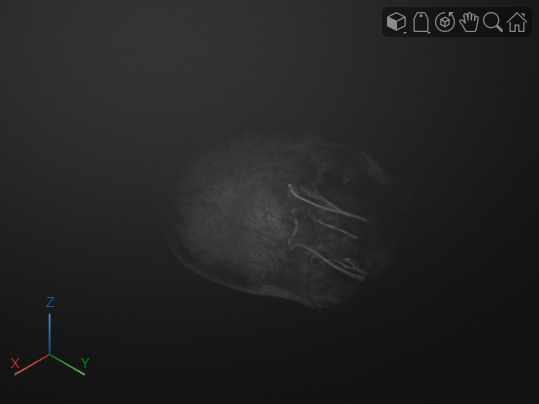

disp("Dimensiones volumen escalado: ")
disp(size(VOL_OUT));

figure('Name','Volumen Escalado - 3D');
volshow(VOL_OUT);
figure('Name','Volumen Escalado - Cortes');
sliceViewer(VOL_OUT);




**b) Reconstrucción de imágenes (20pts):** usted dispone de 2 imágenes que se encuentran dañadas con artefactos que son fácilmente visible en su espacio k.

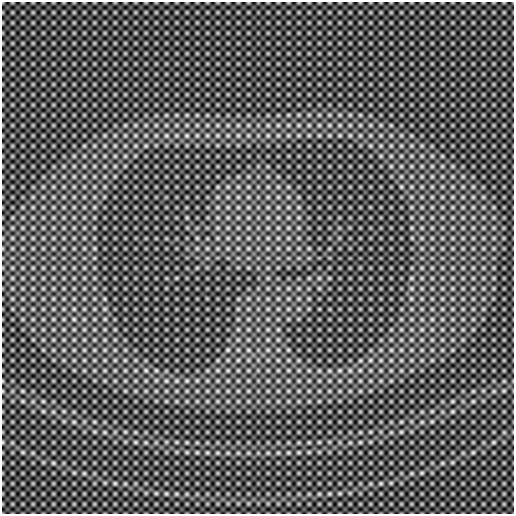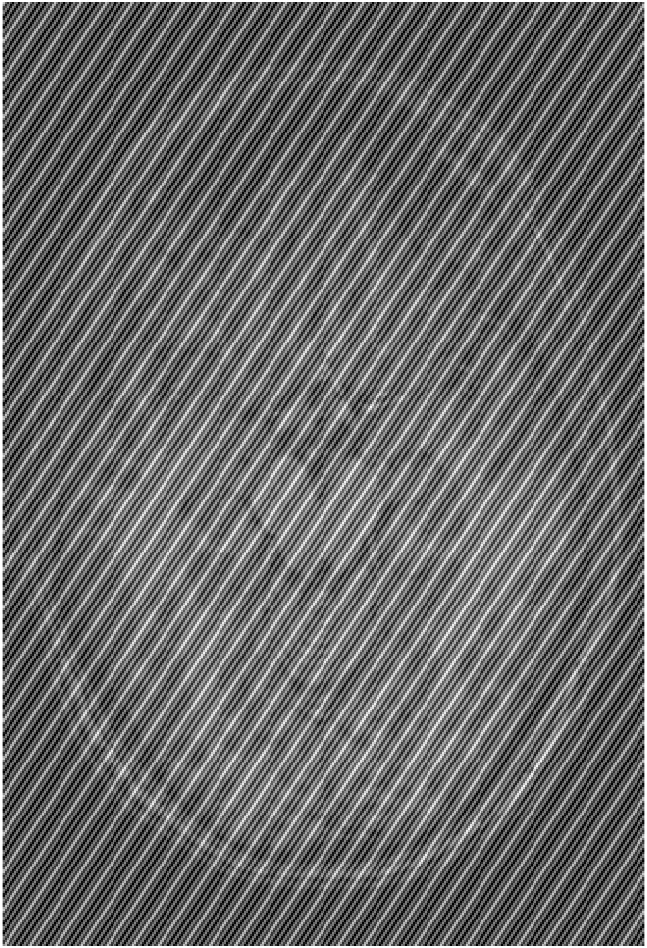

Implemente la estrategia que usted estime conveniente para poder corregir este problema y reconstruir la imagen lo mejor posible. Describa detalladamente que estrategia siguió. ***No está autorizado de usar las funciones de Matlab, ni para corregir la imagen, ni reconstruir la imagen, debe desarrollar su propio código (Usted puede hacer uso de códigos que desarrollamos en clases) ***

% La estrategia seguida para esta implementación comienza aplicando la
% transformada de Fourier de la imagen con la función fft2 para obtener el espacio-k. 
% Luego se crea una matriz de unos que será la máscara, donde los puntos
% donde estban los picos de luz pasan a ser 0 (puntos obtenidos manualmente al 
% revisar el espacio-k, y pasados como parámetros a la función).
% Finalmente se aplica la máscara sobre el espacio-k  mediante multiplicación 
% punto a puntoy con la transformadainversa de Fourier se reconstruye la imagen final. 


function reconstruccion(img, pares, nombre)

    % Transformada de Fourier
    F = fft2(img);

    % Centrar frecuencias bajas en el medio
    F_centrada = fftshift(F);

    % Magnitud para visualizar
    K = log(1 + abs(F_centrada));

    % Máscara
    mask = ones(size(F_centrada));

    for i = 1:length(pares)
        par = pares{i};
        x = par(1);
        y = par(2);
        mask(x, y) = 0;
    end
    
    % Aplicar la máscara en el espacio-k
    F_filtrado = F_centrada .* mask;

    % Reconstruir la imagen en el dominio espacial
    img_reconstruida = ifft2(ifftshift(F_filtrado));

    % Mostrarmos el resultado
    figure;

    subplot(1,3,1);
    imagesc(img);
    colormap gray;
    axis image;
    title(['Imagen original ' nombre]);

    subplot(1,3,2);
    imagesc(K);
    colormap gray;
    axis image;
    title(['Espacio-k de ' nombre]);
    datacursormode on;

    subplot(1,3,3);
    imagesc(real(img_reconstruida));
    colormap gray;
    axis image;
    title(['Imagen ' nombre ' reconstruida']);

end

(b)


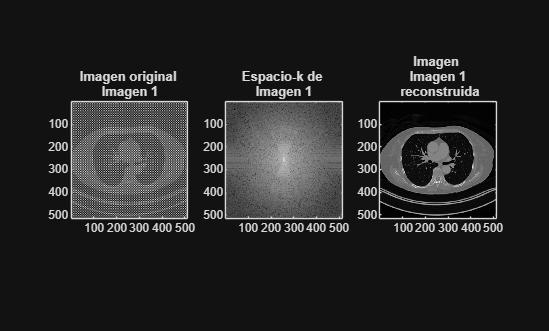


disp("(b)");
%Llamamos para la primera:
pares1 = {
    [207, 207]
    [207, 257]
    [207, 307]
    [257, 207]
    [257, 307]
    [307, 207]
    [307, 257]
    [307, 307]
};


DATA1 = load(fullfile('IMAGENES_TAREA1','DATOS_TAREA1_PREGUNTA_B','im1.mat'));
img1 = double(DATA1.im1);

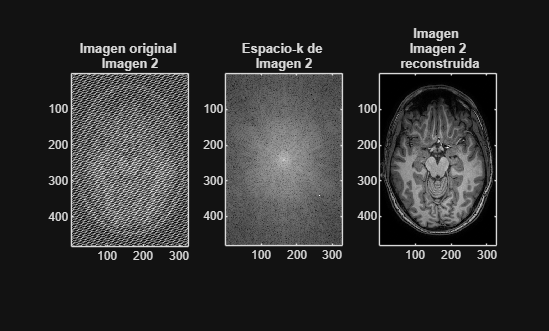


reconstruccion(img1, pares1, "Imagen 1");

% Llamamos para la segunda:
pares2  = {
    [141, 64]
    [191, 114]
    [216, 139]
    [266, 189]
    [291, 214]
    [341, 264]
};
DATA2 = load(fullfile('IMAGENES_TAREA1','DATOS_TAREA1_PREGUNTA_B','im2.mat'));
img2 = double(DATA2.im2);


reconstruccion(img2, pares2, "Imagen 2");

**c) Retroproyección (20 pts):** Usted dispone de los siguientes sinogramas, de dos imágenes desconocidas. 

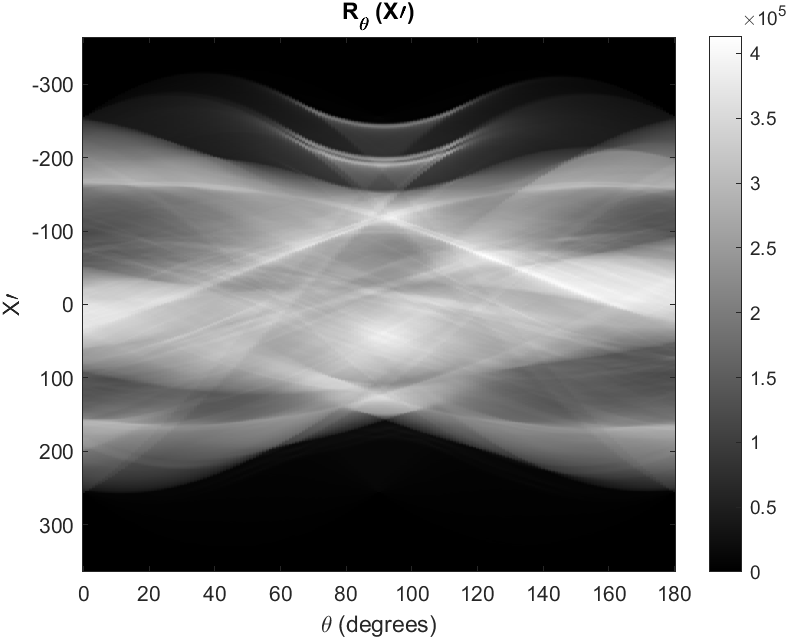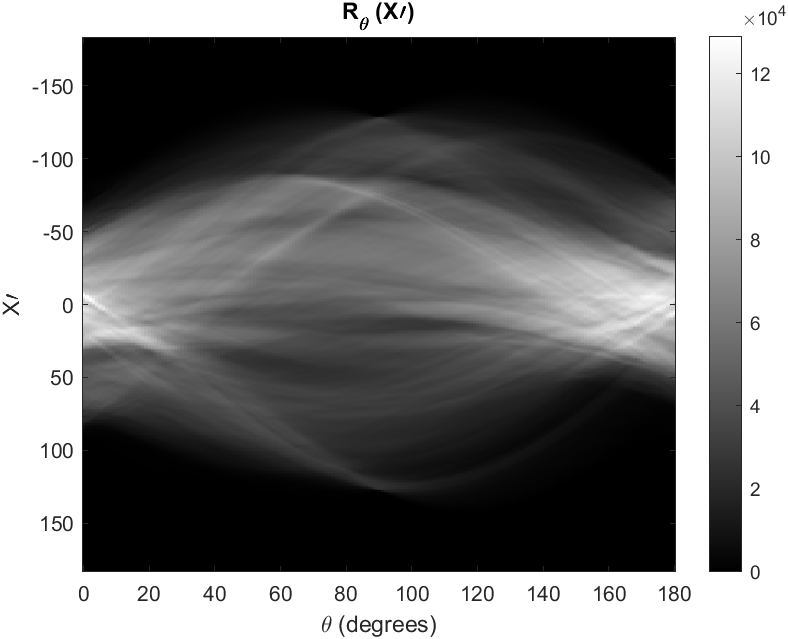

Realice la reconstrucción de la imagen original de cada uno de ellos usando retroproyección con y sin filtrar. Adicionalmente a partir de sus retroproyecciones filtradas, reconstruya la imagen resultante usando la transformada de fourier. ***No se pueden usar las funciones de la transformada de radón o iradon de Matlab, debe desarrollar su propio código. (Si esta permitido usar funciones de rotación en caso de necesitar y las funciones de la transformada de Fourier para filtrar las señales que se usaran posteriormente en cada retroproyección).***

% Reminder. Para cada sinograma:
% 1. Retroproyección simple
% 2. Retroproyección filtrada
% 3. Reconstrucción con Furier en base a la retroproyección filtrada
% Explico cada algoritmo dentro de las funciones. 


function img_rec = retroproyeccion_simple(sino)
    % La función implementada recibe el sinorgrama para aplicar
    % retroproyección simple. Comienza obteniendo las dimensiones del
    % sinograma recibido, donde cada columna corresponde a un ángulo
    % distinto. Luego inicializa una imagen cuadrada de salida. 
    % PAra cada ángulo, toma la proyección correspondiente y la replica en
    % forma de banda, formando una imagen donde cada fila es gual a la
    % proyección original.
    % La banda se va rotando con imrotate según su ángulo asociado por
    % interpolación bilineal, alineándola a su orientación original. Así al
    % finalizar este proceso con todas las bandas, se obtiene la imagen
    % final.
    [num_detectores, num_angulos] = size(sino);
    N = num_detectores;
    img_rec = zeros(N,N);
    angulos = linspace(0,180,num_angulos);

    for k = 1:num_angulos
        proyeccion = sino(:,k);
        banda = repmat(proyeccion,1,N);
        banda_rotada = imrotate(banda,-angulos(k),'bilinear','crop');
        img_rec = img_rec + banda_rotada;

    end
end

function img_rec = retroproyeccion_filtrada(sino)
    % Al igual que en la versión simple, comienza obteniendo las
    % dimensiones del sinograma recibido e inicializando una imagen
    % cuadrada para la salida.
    % La diferencia principal es que, antes de hacer la retroproyección,
    % cada proyección es filtrada en el dominio de Fourier. Para ello, se
    % calcula la transformada de Fourier 1D de cada proyección y se
    % multiplica por el filtro tipo 'rampa' + una ventana 'Hann', que fue de 
    % todo lo que mejor funcionó. 
    % Luego, se aplica la transfrmada inversa para obtener la proyección
    % filtrada en el dominio espacial. Esta proyección nuevamente se
    % replica en forma de banda y se rota según su ángulo asociado mediante
    % imrotate aplicando interpolación bilineal.
    % Al sumar todas las bandas en la imagen vacía inicializada, se obtiene
    % la imagen final de salida. 
    % Notar que se produce pérdida de información y precisión al hacer
    % interpolación y rotación de la imagen, lo que podría explicar los
    % trazos y artefactos que 

    [num_detectores, num_angulos] = size(sino);
    N = num_detectores;
    img_rec = zeros(N,N);
    angulos = linspace(0,180,num_angulos);

    % Filtro Hann !!
    n = floor(num_detectores/2);
    freq = (-n:n)';
    f = freq / max(abs(freq));
    filtro = abs(f) .* (0.5 + 0.5*cos(pi*f));

    for k = 1:num_angulos
        r = sino(:,k);
        R = fftshift(fft(r));

        % Aplicar filtro rampa
        R_filtrado = R .* filtro;

        r_filtrada = real(ifft(ifftshift(R_filtrado)));
        banda = repmat(r_filtrada,1,N);

        % Retroproyectar
        banda_rotada = imrotate(banda,-angulos(k),'bilinear','crop');
        img_rec = img_rec + banda_rotada;

    end
end

%% PENDIENTE RECONSTRUCCIÓN CON FURIER!!!!

function main(sino)
    img_rec = retroproyeccion_simple(sino);
    img_rec_filtrada = retroproyeccion_filtrada(sino);
    figure;

    % Retroproyección simple
    subplot(1,2,1);
    imagesc(img_rec);
    colormap gray;
    axis image;
    title('Retroproyección simple');
    
    % Retroproyección filtrada
    subplot(1,2,2);
    imagesc(img_rec_filtrada);
    colormap gray;
    axis image;
    title('Retroproyección filtrada');
end

(c)


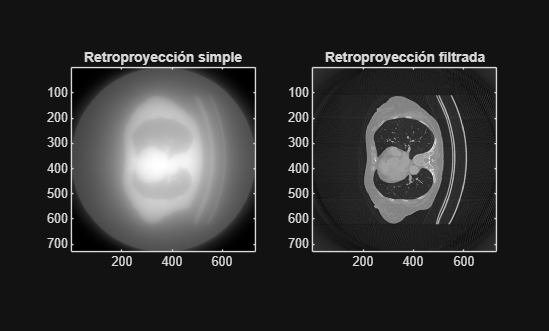


disp("(c)");
%Llamado:
%Imagen 1:
DATA1 = load(fullfile('IMAGENES_TAREA1','DATOS_TAREA1_PREGUNTA_C','sinogram1.mat'));
nombres = fieldnames(DATA1);
sino = DATA1.(nombres{1});

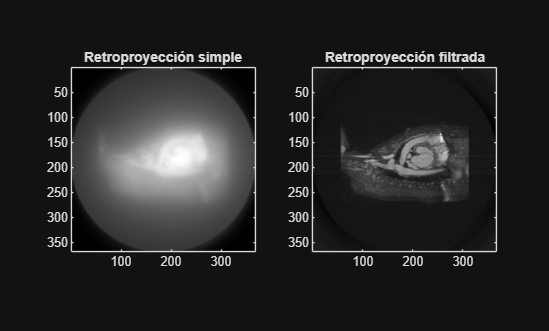

sino = double(sino);
main(sino)

DATA2 = load(fullfile('IMAGENES_TAREA1','DATOS_TAREA1_PREGUNTA_C','sinogram2.mat'));
nombres = fieldnames(DATA2);
sino = DATA2.(nombres{1});

sino = double(sino);
main(sino)







**d) Reconstrucción de imágenes paralelas:** A partir de la imagen de cerebro *m.mat *y las sensibilidades de las bobinas entregadas en *C.mat*, genere la imagen obtenida por cada bobina y realice lo siguiente:

**d.1) (5 pts)** Reconstruya la imagen a partir de las múltiples bobinas, utilizando la ecuación de suma de cuadrados.  


$$m\left(r\right)=\sqrt{\sum_{i=1}^{N_c } |m_i \left(r\right)|^2 }$$


% El algoritmo comienza cargando los archivos de  imagen y de las
% sensibilidades. Esto se hará igual en d.1, d.2, d.3 y d4. 
% Luego, genera la imagen de cada bobina mutiplicando la imagen original
% por cada uno de los mapas de sensibilidad con repmat(), obteniendo un
% conjunto de imágenes donde cada bobina aporta una versión ligeramente
% diferente según su sensibilidad.

% Después se aplica el método de suma de cuadrados con la ecuación
% proporcionada, combinando todo el resultado en una única imagen final.

% El resultado es una aproximación de la imagen original, con variaciones
% leves en intensidad por las sensibilidades de las bobinas. 

function suma_de_cuadrados()

    % Carga de archivos:
    DATA_m = load(fullfile('IMAGENES_TAREA1', 'DATOS_TAREA1_PREGUNTA_D', 'm.mat'));
    DATA_C = load(fullfile('IMAGENES_TAREA1', 'DATOS_TAREA1_PREGUNTA_D','C.mat'));
    nombres_m = fieldnames(DATA_m);
    nombres_C = fieldnames(DATA_C);
    m = DATA_m.(nombres_m{1});
    C = DATA_C.(nombres_C{1});
    m = double(m);
    C = double(C);

    % Imagen de cada bobina
    Nc = size(C,3);
    rec_by_coil = repmat(m,1,1,Nc) .* C;
    

    % Suma de cuadrados
    img_final = sqrt(sum(abs(rec_by_coil).^2,3));

    % Mosrtar
    figure;
    imagesc(img_final);
    colormap gray;
    axis image;
    title('Reconstrucción d1 (Suma de Cuadrados)');


(d.1)


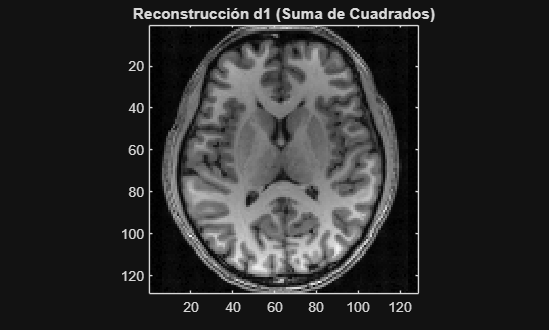

end

disp("(d.1)");
suma_de_cuadrados()


**d.2) (5 pts) **Reconstruya la imagen a partir de las múltiples bobinas, utilizando la ecuación de combinación de sensibilidad pesadas. 


$$m\left(r\right)=\frac{\sum_{i=1}^{N_c } c_i^* \left(r\right)m_{i\left(r\right)} }{\sqrt{\sum_{i=1}^{N_c } |c_i \left(r\right)|^2 }}$$


% Tras cargar los archivos, nuevamente se genera la imagen para cada bobina.
% La diferencia es que, en vez de combinar las imágenes con una suma
% de cuadrados, se pondera la imagen de cada bobina según su sensibilidad.
% Para ello se caclula un numerador que combina las imágenes de cada bobina
% multiplicadas por le conjugado de sus sensibilidades, y en el denominador
% se hace la suma de las magnitudes al cuadrado de cada sensibilidad. 

% Finalmente, se realiza la división, incorporando un checkeo para evitar
% que se rompa si el denominador se hace cero. El restultado es la
% reconstrucción ponderada de cada pixel según la sensibilidad de las
% bobinas.

% La imagen resultante presenta una mejoría en iluminación y contraste
% frente a la obtenida por suma de cuadrados, especialmente en aquellas
% zonas centrales donde predoniban los colores grises más oscuros. 

function comb_sensibilidad_pesadas()

    %Carga de archivos:
    DATA_m = load(fullfile('IMAGENES_TAREA1', 'DATOS_TAREA1_PREGUNTA_D', 'm.mat'));
    DATA_C = load(fullfile('IMAGENES_TAREA1', 'DATOS_TAREA1_PREGUNTA_D','C.mat'));
    nombres_m = fieldnames(DATA_m);
    nombres_C = fieldnames(DATA_C);
    m = DATA_m.(nombres_m{1});
    C = DATA_C.(nombres_C{1});
    m = double(m);
    C = double(C);

    % Imagen de cada bobina
    Nc = size(C,3);
    rec_by_coil = repmat(m,1,1,Nc) .* C;

    % Ec. (esta es la combinacion en sí misma, el resto es preparacion)
    numerador = sum(conj(C) .* rec_by_coil, 3);
    denominador = sum(abs(C).^2, 3);
    denominador(denominador == 0) = eps;
    img_final = abs(numerador ./ denominador);

    % Mostrar resultado
    figure;
    imagesc(img_final);
    colormap gray;
    axis image;
    title('Reconstrucción d2 (sensibilidad pesada)');


(d.2)


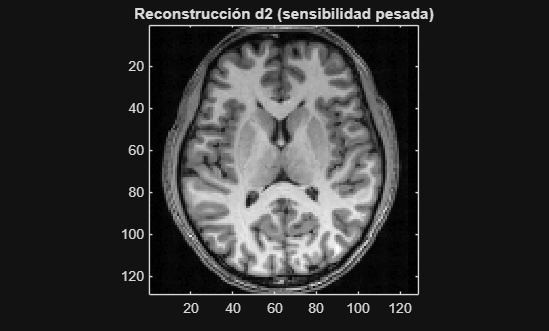

end

disp("(d.2)");
comb_sensibilidad_pesadas()


**d.3) (10 pts)** Aplique el método de reconstrucción SENSE de imágenes paralelas visto en el código de ejemplo de Matlab para un submuestreo x4, x6, x8. Muestre en pantalla las imágenes de cada una de las bobinas sub-muestreadas y también entregue la imagen reconstruida final. Comente acerca de los resultados obtenidos. 

% Nuevamente se cargan los archivos y se genera la imagen de cada bobina
% multiplicando la original por la sensibilidad de cada una. 

% Luego se aplica un submuestreo uniforme en el espcio-k, conservando sólo
% una de cada X líneas, donde X es el submuestreo especificado. Esto
% provoca aliasing en las imágenes reconstruidas por bobina, ya que
% distintas posiciones quedan superpuestas. 

% A partir de este espacio-k submuestrado, se obtiene la imagen de cada
% bobina con la transformada inversa de Fourier, resultando en imágenes
% aliasadas.

% Ahora se aplica el méotodo SENSE, para eliminar el aliasing. Para ello
% en cada píxel se consideran las sensibilidades de las bobinas y se
% construye un sistema de ecuaciones que relaciona las mediciones con los
% valores reales. Al resolverlo con matriz pseudoinversa se obtiene la
% estimación de los valores originales de los píxeles.
% Finalmente, se normaliza la imagen reconstruida.

% Notar que la imagen tiene 128 filas y existen 8 bobinas. En los resultados, 
% los factores x4 y x8 funcionan correctamente, mientras que x6 presenta 
% una fuerte degradación. Esto se debe a que 128 es divisible por 4 y 8, 
% generando un plegamiento regular de la imagen, mientras que 128/6 no es 
% entero, produciendo agrupaciones irregulares de aliasing.

% 128 / 4 = 32 (No se rompe)
% 128 / 8 = 16 (No se rompe)
% 128 / 6 = 21.333... (Se rompe)

% En los casos x4 y x8, la imagen reconstruida presenta buena uniformidad 
% de intensidad y contraste en todo el cerebro. En cambio, para x6 aparecen 
% franjas brillantes y pérdida significativa de información, lo que se evidencia 
% también en la imagen de diferencia, donde gran parte del contenido no coincide 
% con la imagen original.

function metodo_sense(submuestreo)
    
    %Carga de archivos:
    DATA_m = load(fullfile('IMAGENES_TAREA1', 'DATOS_TAREA1_PREGUNTA_D', 'm.mat'));
    DATA_C = load(fullfile('IMAGENES_TAREA1', 'DATOS_TAREA1_PREGUNTA_D','C.mat'));
    nombres_m = fieldnames(DATA_m);
    nombres_C = fieldnames(DATA_C);
    m = DATA_m.(nombres_m{1});
    C = DATA_C.(nombres_C{1});
    m = double(m);
    C = double(C);

    % Imagen de cada bobina
    Nc = size(C,3);
    rec_by_coil = repmat(m,1,1,Nc) .* C;
    
    % submuestreo uniforme
    mask = zeros(size(C));
    mask(1:submuestreo:end,:,:) = mask(1:submuestreo:end,:,:) + 1;
    
    espacio_k = [];
    espacio_k_sub = [];
    brain_sub = [];


    % imágenes submuestreadas por bobina
    for n=1:size(C,3)
        espacio_k(:,:,n) = fftshift(fft2(rec_by_coil(:,:,n))).*mask(:,:,n);
        espacio_k_sub(:,:,n) = espacio_k(1:submuestreo:end,:,n);
        brain_sub(:,:,n) = ifft2(fftshift(espacio_k_sub(:,:,n)));
    end


    % reconstrucción SENSE
    M  = size(brain_sub,1);
    N  = size(brain_sub,2);
    MM = size(C,1);
    
    IMSENSE = complex(zeros([MM,N]));

    for jj=1:M
        for ii=1:N
    
            filas = jj:M:MM;
    
            CC = squeeze(C(filas,ii,:)).';
            a  = squeeze(brain_sub(jj,ii,:));
    
            IMSENSE(filas,ii) = pinv(CC)*a;
    
        end
    end
    
    IMSENSE = abs(IMSENSE);
    IM_R = IMSENSE/max(IMSENSE(:));
    
    
    figure;
    
    subplot(1,3,1)
    imshow(m,[])
    title('Original')
    
    subplot(1,3,2)
    imshow(IM_R,[])
    title(['SENSE x',num2str(submuestreo)])
    
    subplot(1,3,3)
    imshow(abs(m-IM_R),[])
    title('Diferencia')

end

(d.3)


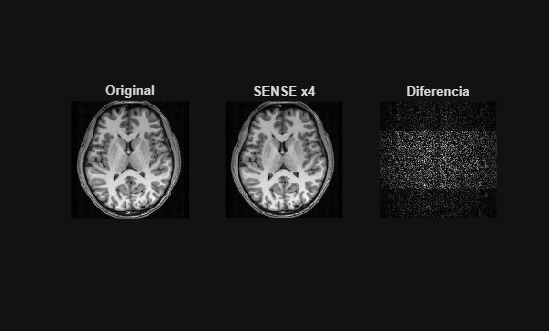


disp("(d.3)");


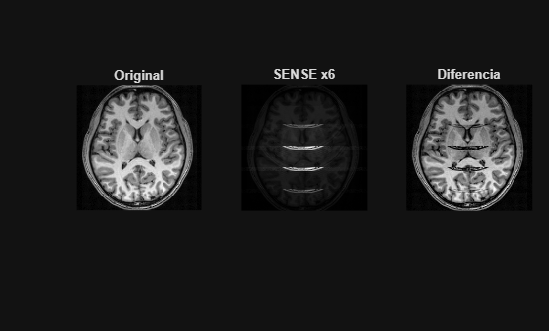

% Llamados para x4, x6 y x8

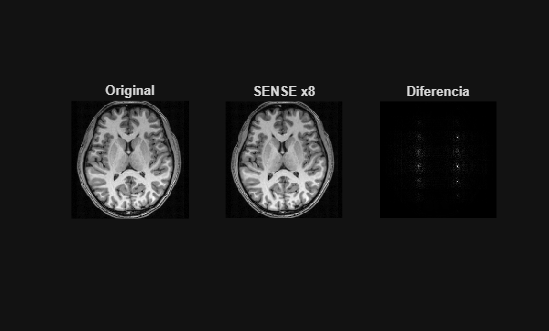

metodo_sense(4); 

metodo_sense(6); 
metodo_sense(8); 

**d.4) (20 pts) **Finalmente investigue acerca del método de reconstrucción GRAPPA (Generalized autocalibrating partially parallel acquisitions), e impleméntelo a cada una de las imágenes de las bobinas con submuestreo x2, y reconstruya la imagen resultante con la ecuación de combinación de sensibilidad pesadas. Puede mirar el paper original de GRAPPA, para orientarse ([https://doi.org/10.1002/mrm.10171](https://doi.org/10.1002/mrm.10171)). 

(d.4)


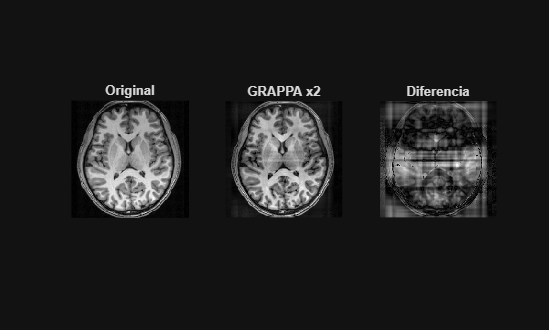

% GRAPPA es un método de reconstrucción de datos de MRI paralela de múltiples bobinas.
% Trabaja con el espacio-k y reconstruye datos faltantes de una bobina con información conjunta de todas.
% Esto lo hace con líneas centrales completamente adquiridas, denominadas ACS (Auto Calibration Signal),
% con las cuales estima pesos de reconstrucción que permiten interpolar datos faltantes del espacio-k de la bobina.
%
% Una de las principales ventajas del método es la no necesidad de mapas explícitos de sensibilidades
% de las bobinas que, como se explica en el paper, pueden ser complejos de obtener o de medir con precisión
% por elementos como el ruido.
% En vez de esto, usa los ACS para hacer la estimación de puntos faltantes en los espacios-k
% de cada bobina de forma combinada.
%
% Una vez reconstruido el espacio-k de cada bobina, se aplica la transformada inversa de Fourier
% para obtener la imagen individual de cada una de las bobinas.
% Finalmente, se aplica algún método como suma de cuadrados o combinación pesada
% para combinar todas las imágenes en la imagen final.
%
% Nota: Como no se dispone del espacio-k por bobina, en esta tarea fue necesario
% utilizar el mapa de sensibilidades para generar cada espacio-k.
%
% Descripción de mi implementación:
%
% Mi implementación usa un kernel en vez de los bloques que menciona el paper,
% para tener un enfoque más parecido al visto en clases de otros métodos,
% pero la lógica general es muy similar.
%
% Elegí un tamaño de 2x3 para el kernel por simpleza.
% Notar que no es cuadrado tipo 3x3 porque falta información de la línea central,
% por lo que solo se utilizan las líneas superior e inferior junto con contexto horizontal.
%
% Usé 16 líneas ACS porque en el paper se presentó la idea de usar 8 o 16 indistintamente.
% Funcionó bien con ambos valores.
%
% El código sigue la siguiente lógica:
%
% 1. Genera el espacio-k de cada bobina con transformada de Fourier.
% 2. Simula submuestreo (x2) y conserva la región central ACS completa.
% 3. Extrae las líneas ACS para usarlas como datos de calibración.
% 4. Forma ejemplos de entrenamiento con el kernel sobre la región ACS.
% 5. Calcula los pesos GRAPPA.
% 6. Reconstruye los puntos faltantes del espacio-k submuestreado usando esos pesos.
% 7. Aplica transformada inversa de Fourier para recuperar la imagen de cada bobina.
% 8. Combina todas las bobinas mediante ponderación por sensibilidad para obtener la imagen final.


function metodo_GRAPPA()

    %Carga de archivos:
    DATA_m = load(fullfile('IMAGENES_TAREA1','DATOS_TAREA1_PREGUNTA_D','m.mat'));
    DATA_C = load(fullfile('IMAGENES_TAREA1','DATOS_TAREA1_PREGUNTA_D','C.mat'));
    nombres_m = fieldnames(DATA_m);
    nombres_C = fieldnames(DATA_C);
    m = double(DATA_m.(nombres_m{1}));
    C = double(DATA_C.(nombres_C{1}));

    % Imagen de cada bobina
    Nc = size(C,3);
    rec_by_coil = repmat(m,1,1,Nc) .* C;

    % Espacio-k de cada bobina
    for i = 1:Nc
        espacio_k(:,:,i) = fft2(rec_by_coil(:,:,i));
    end

    % Submuestreo x2 para simular luego el GRAPPA
    [Ny, Nx, Nc] = size(espacio_k);
    espacio_k_submuestreo = zeros(size(espacio_k));

    % Aquí el submuestreo per-sé
    cant_lineas_acs = 16;
    espacio_k_submuestreo(1:2:end,:,:) = espacio_k(1:2:end,:,:);

    inicio = floor(Ny/2) - floor(cant_lineas_acs/2) + 1;
    fin    = inicio + cant_lineas_acs - 1;

    % Reconstruir las líneas centrales completas (ACS)
    espacio_k_submuestreo(inicio:fin,:,:) = espacio_k(inicio:fin,:,:);

    % Extraer región ACS completa
    acs = espacio_k(inicio:fin,:,:);

    % Matrices de entrenamiento GRAPPA
    X = [];
    Y = [];

    % Kernel 2D usando vecinos arriba y abajo
    for y = 2:2:size(acs,1)-1
        for x = 2:Nx-1

            arriba = acs(y-1,x-1:x+1,:);
            abajo  = acs(y+1,x-1:x+1,:);

            entrada = [arriba(:); abajo(:)].';

            objetivo = reshape(acs(y,x,:),1,[]);

            X = [X; entrada];
            Y = [Y; objetivo];

        end
    end

    % Calcular pesos GRAPPA
    W = pinv(X) * Y;

    % Copiar el espacio k submuestrado para reconstrucción
    espacio_k_reconstruido = espacio_k_submuestreo;

    for y = 2:2:Ny-1
        if y < inicio || y > fin

            for x = 2:Nx-1

                arriba = espacio_k_reconstruido(y-1,x-1:x+1,:);
                abajo  = espacio_k_reconstruido(y+1,x-1:x+1,:);

                entrada = [arriba(:); abajo(:)].';

                % Estimación punto faltante
                punto_estimado = entrada * W;

                espacio_k_reconstruido(y,x,:) = reshape(punto_estimado,[1 1 Nc]);

            end
        end
    end

    % Volver a imagen por cada bobina reconstruida
    for i = 1:Nc
        img_rec(:,:,i) = ifft2(espacio_k_reconstruido(:,:,i));
    end

    % Combinación pesada por sensibilidad
    numerador = sum(conj(C) .* img_rec, 3);
    denominador = sum(abs(C).^2, 3);
    denominador(denominador == 0) = eps;

    img_final = abs(numerador ./ denominador);
    img_final = img_final / max(img_final(:));

    % Mostrar resultados
    figure;

    subplot(1,3,1)
    imshow(m,[])
    title('Original')

    subplot(1,3,2)
    imshow(img_final,[])
    title('GRAPPA x2')

    subplot(1,3,3)
    imshow(abs(m - img_final),[])
    title('Diferencia')

end

disp("(d.4)");
metodo_GRAPPA();